# Lab 2: Biointerfacing with the Myo Armband

Look for sections of the lab requiring data to be recorded for the lab report, indicated by this icon:  

## Startup the Myo Armband Manager

- Launch the Myo Armband Manager. (Right-Click the tray icon and select “Armband Manager”)

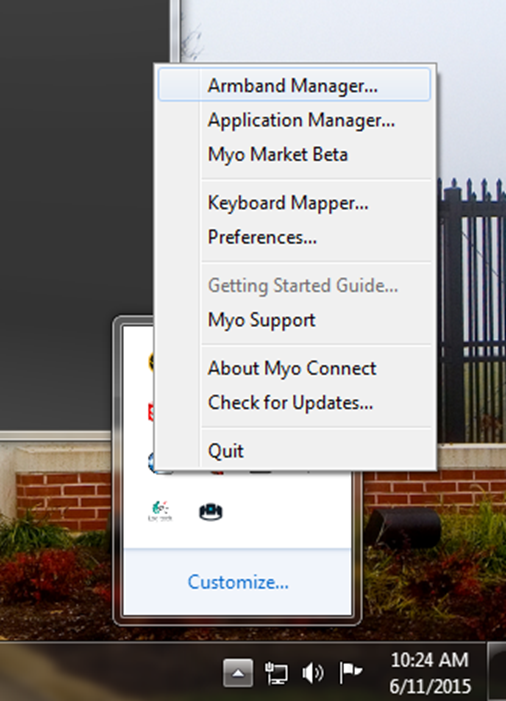        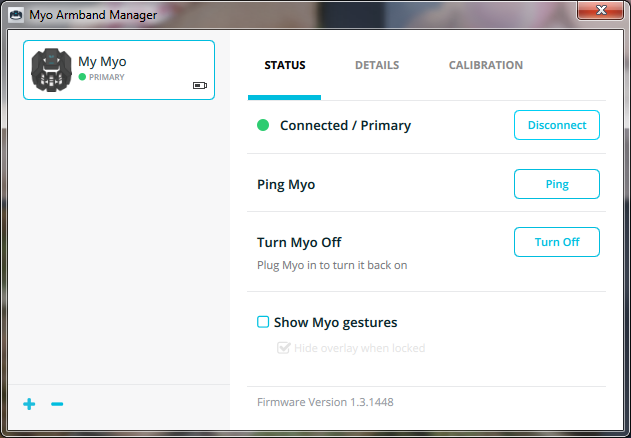

- Ensure the device is connected (Press the “Connect” button)

- Place the Myo on your arm with the logo parallel to the back of your hand

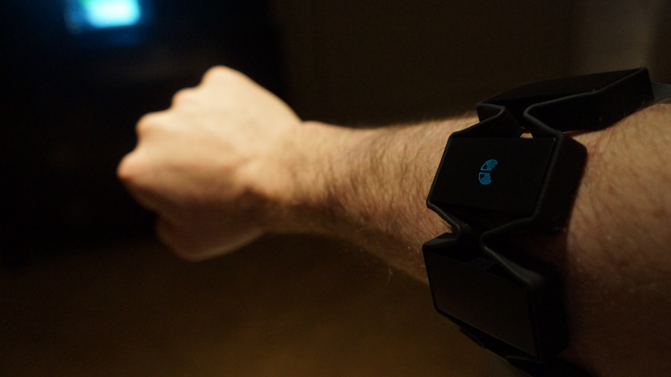

**Note: Myobands will go to sleep after 30 seconds of inactivity (indicated by the blue line LED going off). If you aren’t getting any signals when using the device, reactivate by shaking the armband.  The Myo armband attempts to correct this by periodically vibrating**

- Launch the MyoUdp.exe interface application from the +Inputs directory of the MiniVIE package (suggestion: pin this to your taskbar, you’ll likely use it a bit in this course).

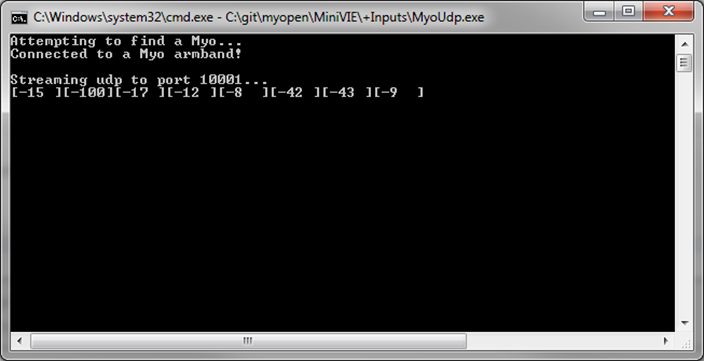

The numbers on the bottom row of this application should be changing.  If not, you're likely not streaming new data.  **Also, make sure you're only running one of these applications at a time!**

## Start the MiniVIE Myo Interface

Create the MATLAB Interface by creating a new script in the MATLAB editor, and enter the following commands.  Note: Upon issuing these commands the first time, this will launch a small executable that handles the device communication.

## Set up the MiniVIE path

cd('C:\Users\smithjl3\Documents\HRI\Drivers\MiniVIE');
MiniVIE.configurePath;

[MiniVIE.m] Configured MiniVIE path at: C:\Users\smithjl3\Documents\HRI\Drivers\MiniVIE



%% Create an object for UDP interface to the Myo Armband
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] myoUdpRate=200
[MyoUdp] UDP Comms already initialized


cd('C:\Users\smithjl3\Documents\HRI\Lab2_EMGInterfacing');

## Plot some EMG Activity

Get some data and plot.  Note: You may have to run getData again if the first graph presents a flat line at zero due to the initialization sequence.

%% Get data and plot.  emgData size is [1000 samples x 8 channels]

%emgData = hMyo.getData;

channels = 8;
time_s = 3; %This variable time is in seconds
SAMPLE_RATE = 1000; %200 = hertz
num_sample = time_s * SAMPLE_RATE;


hMyo.getData(num_sample, 1:channels);


emgDataRight = hMyo.getData(num_sample, 1:channels);

pause(4)

plot(emgData)
xlabel('Sample Number');
ylabel('EMG Signal')

**Example plot:**

## View Streaming EMG

Open the real-time Signal Viewer.  Note: the Signal Viewer uses a MATLAB `timer`() object to automatically update the display.  While it is possible to run other commands, if performance is degraded, close the window when not in use.

hViewer = GUIs.guiSignalViewer(hMyo);

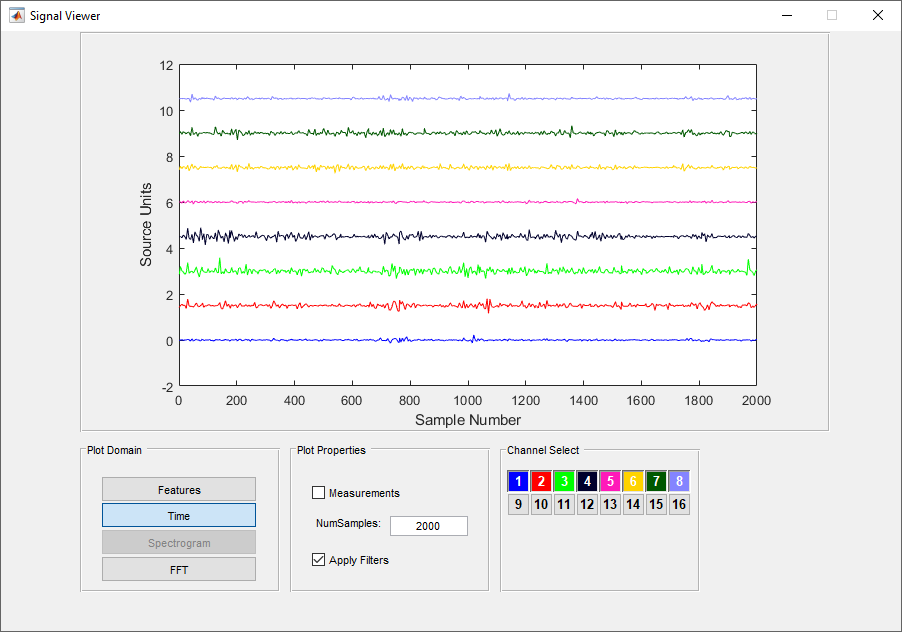

The first time you run this viewer, you will likely need to click on the numbers 1-8 in the channel select window to enable the Myo channel stream.

## Write Some Acquisition Code

 

Write a set of commands / function that will acquire a set of data (using the previous `hMyo.getData `command) and **save the result to a file describing the motion**.  The function buffers incoming data so the get data function represents the previous 1000 ms.  **Plot your results.**

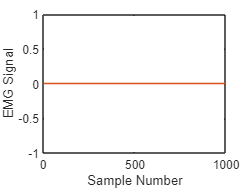

% Write your code to acquire data here

emgData = hMyo.getData;
% Write your code to save your results here

save('myEMGData_Leftie','emgData')
% Write your code to plot your results here
plot(emgData)
xlabel('Sample Number');
ylabel('EMG Signal')

**Copy and paste plots generated by your code here:**

## Studying EMG Patterns

Compute the root mean square amplitude from channels during a few test movements.  Hint: Use the ‘Measurements’ checkbox to observe the Root Mean Square (RMS) and Peak to Peak (Pk-Pk) in the SignalViewer directly to confirm your measurements

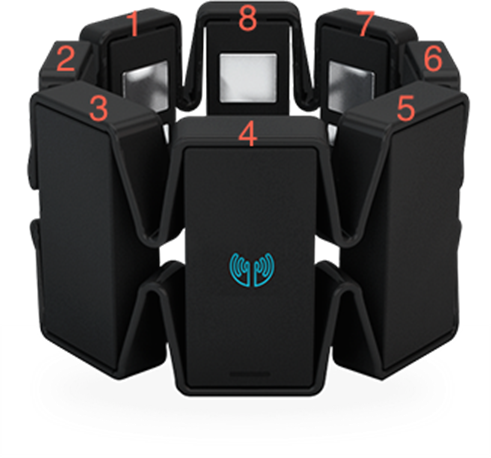

Record the RMS channel values for the 8 channels during the following movements. Please use the table given below.  (Note: For EMG, you must flex muscles as if working against resistance so that the muscle contraction is consistent and measurable.)

                                                                                    **Channel**

**                                                    1        2         3        4       5        6        7         8**

- Example movement:       2.2     0.0     3.3     1.0     0.7     0.5     0.8     1.0 

- Rest                    

- Wrist Flexion

- Wrist Extension

- Wrist Pronation

- Wrist Supination

- Cylindrical Grasp

- Tip Grasp

- Lateral Grasp

- Index Finger

- Middle Finger

- Ring Finger

- Little Finger

**Questions**:

- **Find 2 pairs of movements with very different EMG channel activity.  Do these movements make sense?**

- **Find 2 pairs of movements with very similar EMG channel activity.  Do these movements make sense?**

## Starting the MiniVIE Pattern Recognition Interface

obj = MiniVIE;

If prompted for a configuration file, use the default “user_config.xml”

Set the drop-down menus within the MiniVIE window to those shown in the figure below. For Inputs, select “Thalmic Labs MyoUdp”.  For Signal Analysis, select “LDA Classifier”

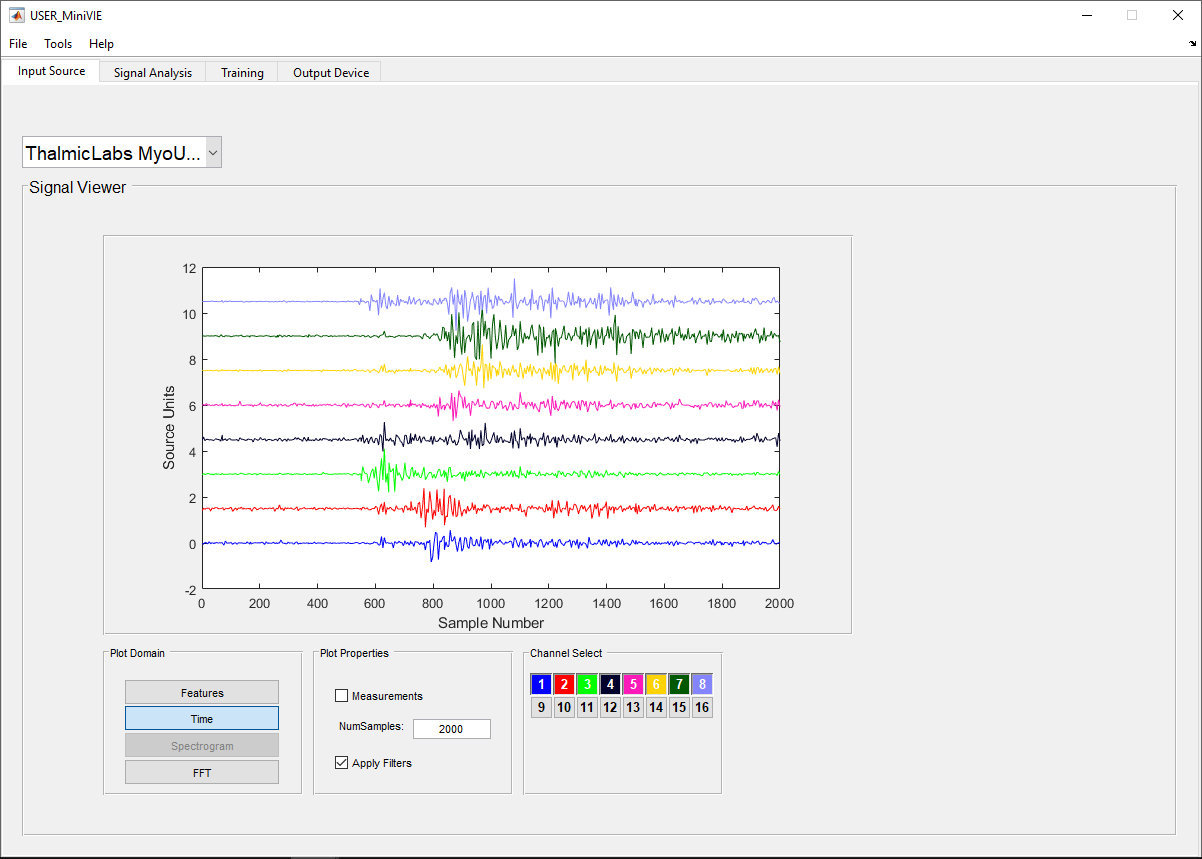

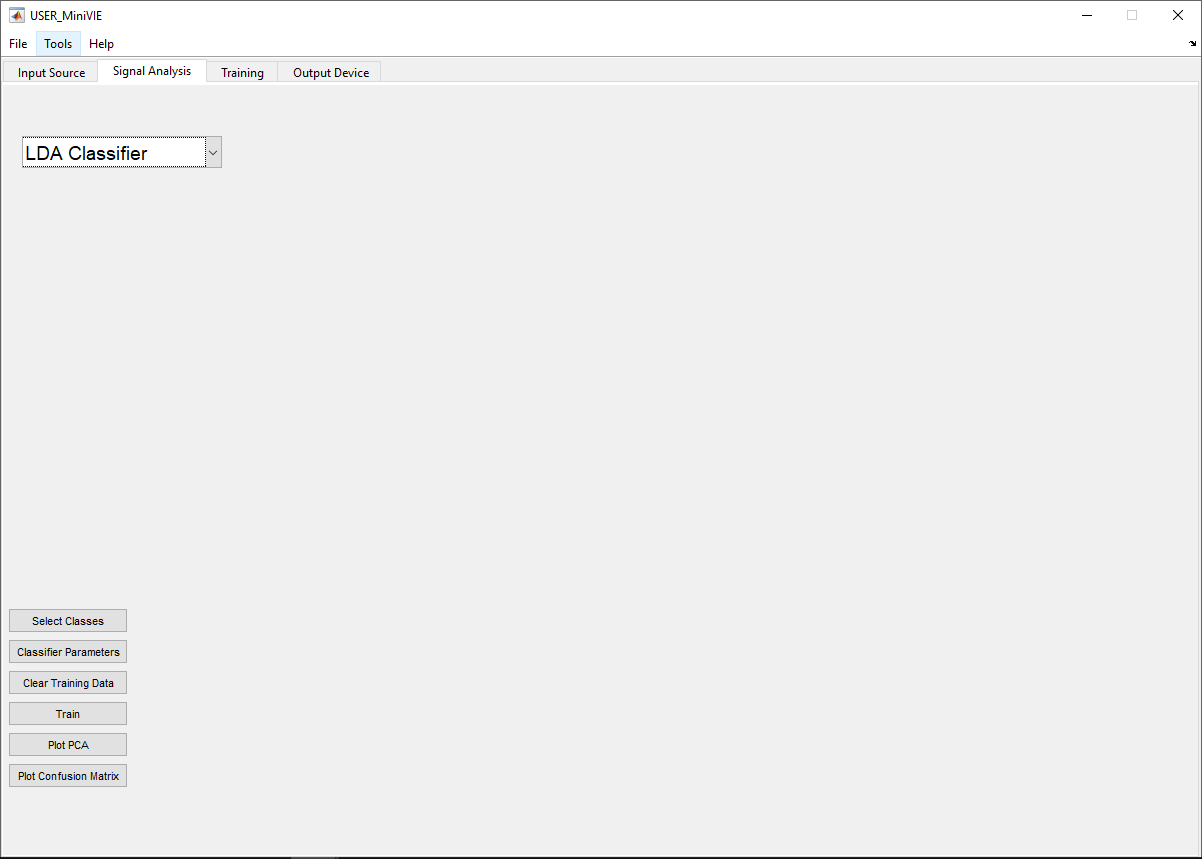

## Collect Training Data

Press the “Select Classes” button to bring up the window for selecting which limb motions to train or classify using the Myoband.  Use the motion classes that you collected EMG data for above.

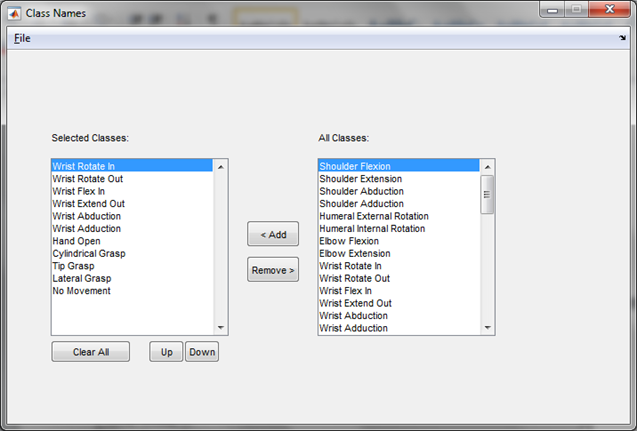

Select the Output Device: “MplUnity”

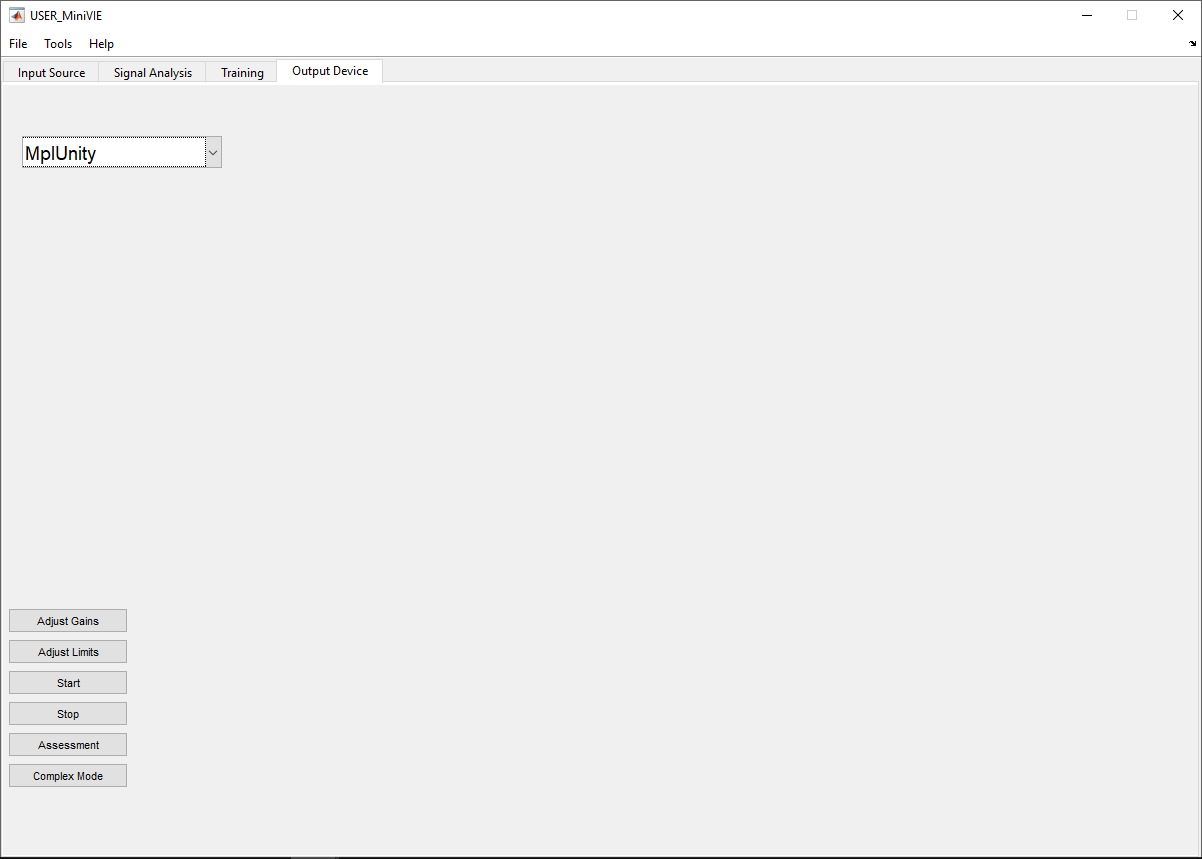

Add data to each of the classes by performing the motion and pressing the “Add” button (press it again to stop collecting).  After a few seconds of relaxing, repeat the process again to add more training data.

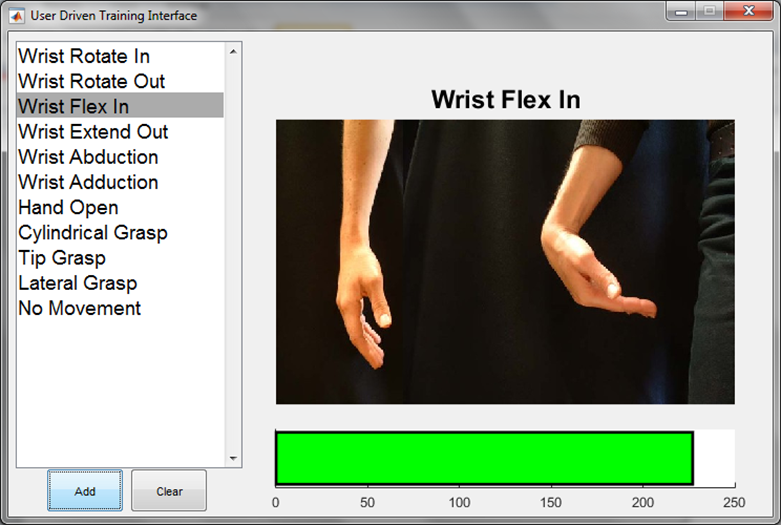

Save your data from the MiniVIE GUI.  File -> Save Training Data.  Save this file as Lab2_##_TrainingData.trainingData in the Lab2 folder under hrilabs/, where ## is your computer number.

## Visualize Your Training Data

Plot the confusion matrix for the movements performed by going to the Signal Analysis tab of the MiniVIE and clicking on Plot Confusion Matrix.  Write down any movements with low prediction accuracy.  Consider potential factors that contributed to error such as similarity of the movement, or improper training.

**Example Plot:**

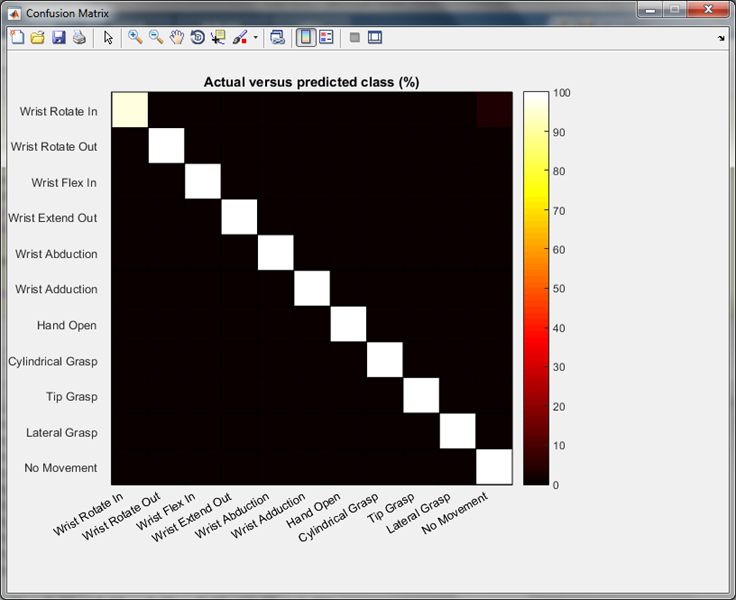

**Paste your plot here:**

**Any low performing classes?**

In addition to the confusion matrix, you can also visualize the Principal Components of the EMG feature data to consider where data might overlap and lead to classification inaccuracies.  Go to the Signal Analysis tab of the MiniVIE and click on Plot PCA.

**Example Plot:**

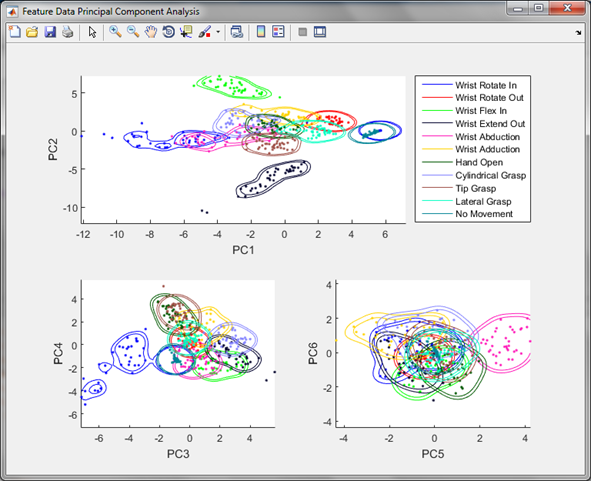

**Paste your plot here:**

## **Submitting This Lab**

Export this *.mlx file as Lab2_##_<LastName1>_<LastName2>.pdf (## should be your computer number) and email to Lauren.Diaz@jhuapl.edu